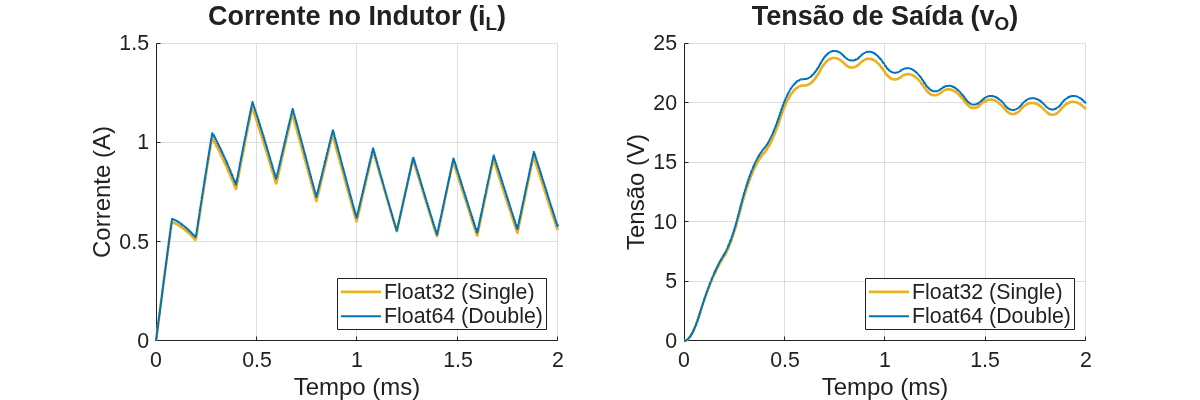

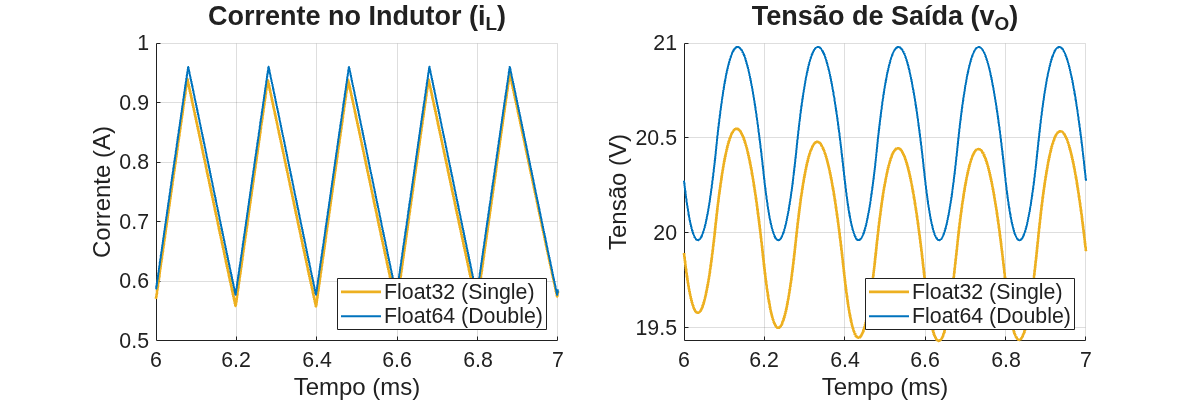

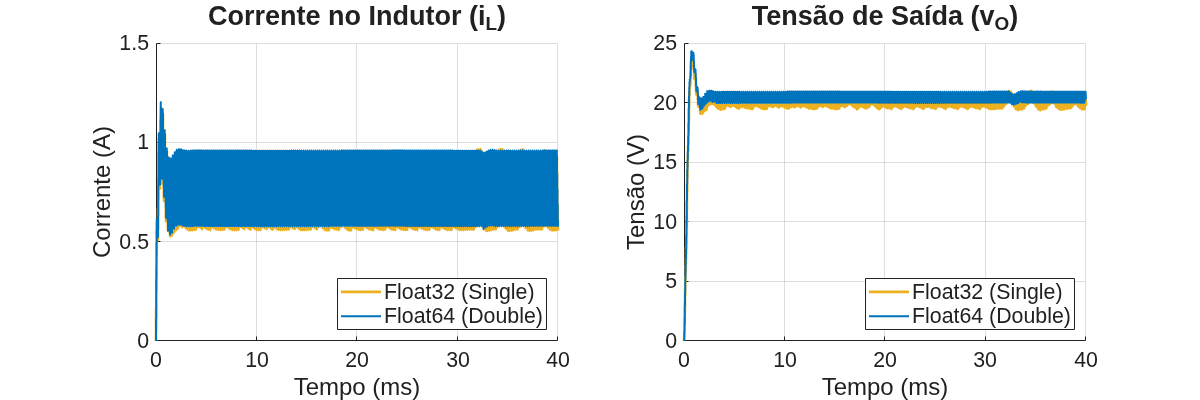

% =========================================================================
% Simulação Discreta de Conversor Buck (Método de Tustin) + LTspice
% Comparação de Precisão: Float32 (single) vs Float64 (double)
% =========================================================================
clear; clc; close all;

% Descobre automaticamente a pasta onde este script (.mlx ou .m) está salvo
documento_ativo = matlab.desktop.editor.getActive();
pasta_deste_script = fileparts(documento_ativo.Filename);

% Muda o diretório de trabalho do MATLAB para essa pasta (se ela existir)
if ~isempty(pasta_deste_script)
    cd(pasta_deste_script);
end

t_total = 40e-3;     % Tempo total de simulação (s) 10ms
T_div = 100;          % Passo fixo em n = 40

% Definindo os tipos de precisão a serem testados
tipos_precisao = {'single', 'double'}; % single = float32, double = float64
nomes_legendas = {'Float32 (Single)', 'Float64 (Double)'};

% Estruturas cell para armazenar os resultados
resultados_t = cell(1, 2);
resultados_iL = cell(1, 2);
resultados_vO = cell(1, 2);

% Garante que ambas as simulações tenham exatamente o mesmo número de passos
% calculando o N_steps em double puro (evita erros de dimensão nos arrays).
Ts_ref = 1.0 / 20e3;
Tsim_ref = Ts_ref / T_div;
N_steps = floor(t_total / Tsim_ref); 

% Loop para testar cada precisão
for idx = 1:length(tipos_precisao)
    dtype = tipos_precisao{idx};
    
    % Função anônima/dinâmica para forçar o tipo de dado correto (single ou double)
    T = str2func(dtype); 
    
    %% 1. Parâmetros de Simulação e do Conversor
    VS = T(50.0);      % Tensão de entrada (V)
    fs = T(5e3);      % Frequência de chaveamento (Hz)
    D  = T(0.4);       % Razão cíclica nominal
    L  = T(6.4e-3);    % Indutância (H)
    C  = T(9.375e-6);     % Capacitância (F)
    R  = T(26.67);      % Resistência de carga (Ohms)

    % Configuração de tempo e discretização na precisão atual
    Ts = T(1.0) / fs;          % Período de chaveamento (s)
    Tsim = Ts / T(T_div);      % Passo de simulação (s) 

    %% 2. Constantes de Discretização (Tustin)
    K1 = Tsim / (T(2.0) * L);
    K2 = (T(2.0) * R * C - Tsim) / (T(2.0) * R * C + Tsim);
    K3 = (R * Tsim) / (T(2.0) * R * C + Tsim);

    % Constantes auxiliares para resolução do laço algébrico
    Den_alg = T(1.0) + K1 * K3;
    K_iL1   = T(1.0) - K1 * K3;
    K_iL2   = K1 * (T(1.0) + K2);

    %% 3. Inicialização das Variáveis de Estado
    vs_old = VS;
    vs_new = VS;
    iL_old = T(0.0); 
    vO_old = T(0.0);

    % Vetores (pré-alocação explícita forçando o tipo na memória)
    t_array = T(0:N_steps-1) * Tsim;
    iL_array = zeros(1, N_steps, dtype);
    vO_array = zeros(1, N_steps, dtype);

    % Armazena as condições iniciais
    iL_array(1) = iL_old;
    vO_array(1) = vO_old;

    %% 4. Loop Principal de Simulação
    for k = 2:N_steps
        t_atual = t_array(k);
        
        vs_new = VS; 
        
        % Mapeia o tempo contínuo para a posição dentro do período
        t_no_periodo = mod(t_atual, Ts); 
        
        if t_no_periodo < (D * Ts)
            chave_fechada = true;
        else
            chave_fechada = false;
        end
        
        % --- Atualização das Variáveis de Estado (mantendo a precisão T) ---
        if chave_fechada
            iL_new = (iL_old * K_iL1 + K1 * (vs_new + vs_old) - K_iL2 * vO_old) / Den_alg;
        else
            iL_new = (iL_old * K_iL1 - K_iL2 * vO_old) / Den_alg;
        end
        
        vO_new = K2 * vO_old + K3 * (iL_new + iL_old);
        
        % --- Armazenamento para os Gráficos ---
        iL_array(k) = iL_new;
        vO_array(k) = vO_new;
        
        % --- Preparação para o Próximo Passo ---
        vs_old = vs_new;
        iL_old = iL_new;
        vO_old = vO_new;
    end
    
    resultados_t{idx} = t_array;
    resultados_iL{idx} = iL_array;
    resultados_vO{idx} = vO_array;
end

%% 5. Geração dos Gráficos

% Define os intervalos de tempo [t_inicial, t_final] em segundos para cada gráfico
intervalos = [
    0.0,     2e-3;   % 0 a 2 ms (Transiente inicial)
    6e-3,    7e-3;   % 6 a 7 ms (Meio da simulação - Regime permanente)
    0.0,     t_total % 0 a 10 ms (Simulação completa)
];

% Títulos correspondentes (corrigidos para bater com os intervalos numéricos)
titulos = {'0 a 2 ms', '6 a 7 ms', '0 a 10 ms'};

% Cores e Estilos Distintos
% Float32 (Mostarda Tracejado), Float64 (Azul Sólido)
cores_matlab = [
    0.93, 0.69, 0.13; % Float32: Amarelo mostarda
    0.00, 0.45, 0.74; % Float64: Azul vibrante
];
estilos = {'-', '-'};
espessuras = [2.0, 1.5];

for n = 1:size(intervalos, 1)
    
    t_min = intervalos(n, 1);
    t_max = intervalos(n, 2);

    figure('Name',['Resposta - ' titulos{n}], 'NumberTitle','off', 'Position', [100, 100, 1200, 400]);

    % ==========================================
    % Corrente do indutor
    % ==========================================
    subplot(1,2,1); 
    hold on;
    % Plota os dados do MATLAB (Float32 e Float64)
    for i = 1:length(tipos_precisao)
        t_aux = double(resultados_t{i});
        iL_aux = double(resultados_iL{i}); % Cast temporário para double só para plotar

        idx = (t_aux >= t_min) & (t_aux <= t_max);
        plot(t_aux(idx)*1e3, iL_aux(idx), 'Color', cores_matlab(i,:), ...
             'LineStyle', estilos{i}, 'LineWidth', espessuras(i));
    end
    hold off;
    grid on;
    
    set(gca, 'FontSize', 16); 
    xlabel('Tempo (ms)', 'FontSize', 18); 
    ylabel('Corrente (A)', 'FontSize', 18); 
    title('Corrente no Indutor (i_L)', 'FontSize', 20); 
    legend(nomes_legendas, 'Location', 'southeast', 'FontSize', 16);

    % ==========================================
    % Tensão de saída
    % ==========================================
    subplot(1,2,2); 
    hold on;
    % Plota os dados do MATLAB (Float32 e Float64)
    for i = 1:length(tipos_precisao)
        t_aux = double(resultados_t{i});
        vO_aux = double(resultados_vO{i});

        idx = (t_aux >= t_min) & (t_aux <= t_max);
        plot(t_aux(idx)*1e3, vO_aux(idx), 'Color', cores_matlab(i,:), ...
             'LineStyle', estilos{i}, 'LineWidth', espessuras(i));
    end
    hold off;
    grid on;
    
    set(gca, 'FontSize', 16); 
    xlabel('Tempo (ms)', 'FontSize', 18); 
    ylabel('Tensão (V)', 'FontSize', 18); 
    title('Tensão de Saída (v_O)', 'FontSize', 20); 
    legend(nomes_legendas, 'Location', 'southeast', 'FontSize', 16);
end